## Code de base


clear all 
close all hidden

syms x ;



% WARNING : note that operations should be done mostly on matrices or
% vectors and adressing separate elmements should NOT be done

% The stiffness matrix is always proportional to K of this form
K=[1 -1 ; -1 1];
H=[1 ; 1];
N=5
 % number of elements = number of INTERVALS between 1 and 4
X=1+[0:N]*(4-1)/(N); % vector of abcissae in x

Ktot=zeros(N+1);
Htot=zeros(N+1,1);

for i=1:N

% the weak formulation yields a stiffness matrix proportional to \int_1^4 x^2 u'v' dx 
% integration done with Matlab : coefficient=int(x^2,X(i),X(i+1)) / (X(i+1)-X(i))^2; 
% or one can directly obtain the analytical integral:
coefficient=(X(i+1)^3-X(i)^3)/(3*(X(i+1)-X(i))^2);
Ki= -coefficient*K; % the local stiffness matrix

% the right-hand inhomogeneous term is also proportional to H vector ;
% beware of the sign, and (x(i+1)-x(i)) is the length of the element
Hi=-(X(i+1)-X(i))*H;

% assemble on the fly the total stiffness matrix and right-hand-side inhomogeneous term vector
Ktot(i:i+1, i:i+1) = Ktot(i:i+1, i:i+1) + Ki;
Htot(i:i+1,1) = Htot(i:i+1,1) + Hi;
end

% introduce boundary conditions u(1)=1 and u(4)=0 (first and last lines and
% columns of the complete linear system of algebraic equations
Htot=Htot - 1*Ktot(:, 1) -0*Ktot(:, N+1);

% solve system (reduced of 2 lines and columns since 2 Dirichlet BCs are
% considered). Beware NOT to inverse the matrix, use the \ operator which
% solves the linear system with an appropriate method (cost is much lower)
Y(2:N)= Ktot(2:N, 2:N) \ Htot(2:N);

% re-install the values of solution at x=1 and x=4 for plotting
Y(1)=1; 
Y(N+1)=0;

% exact solution provided in problem sheet
Yexact=-2*log(X)-1/3 +(8/3)*log(4)+(4/3)*(1-2*log(4))./X;

% plot exact and FE solution
plot(X,Yexact,'-xr', X,Y,'-*b');
hold on 

% compute error
err=sum((Yexact-Y).^2)/sum(Yexact.^2);


$$ans = 0.00012398858477023882974053792249691$$

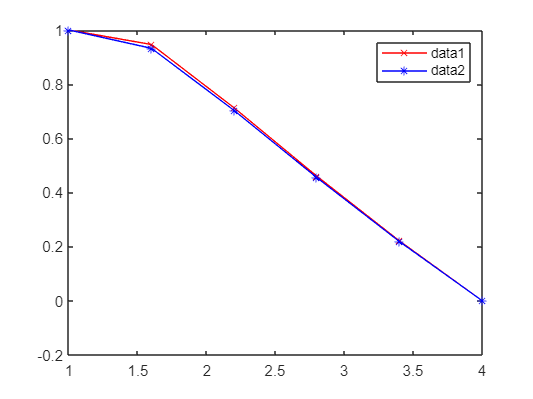


%
legend('show', 'Location','northeast')
%
hold off

## Variation du nombre d'éléments N


clear all 
close all hidden

syms x ;



% WARNING : note that operations should be done mostly on matrices or
% vectors and adressing separate elmements should NOT be done

% The stiffness matrix is always proportional to K of this form
K=[1 -1 ; -1 1];
H=[1 ; 1];

N_liste=5:5:100

N_liste =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


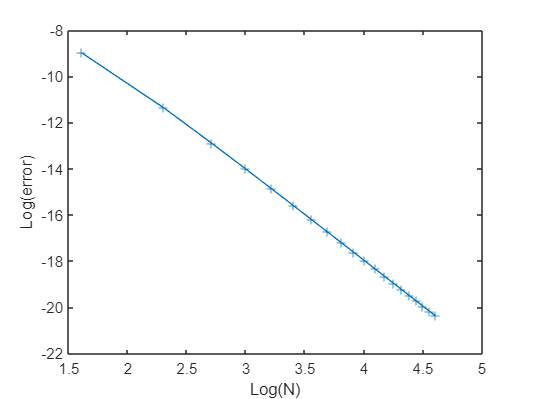

err_liste=zeros(length(N_liste),1);

for N=N_liste
 % number of elements = number of INTERVALS between 1 and 4
X=1+[0:N]*(4-1)/(N); % vector of abcissae in x

Ktot=zeros(N+1);
Htot=zeros(N+1,1);

for i=1:N

% the weak formulation yields a stiffness matrix proportional to \int_1^4 x^2 u'v' dx 
% integration done with Matlab : coefficient=int(x^2,X(i),X(i+1)) / (X(i+1)-X(i))^2; 
% or one can directly obtain the analytical integral:
coefficient=(X(i+1)^3-X(i)^3)/(3*(X(i+1)-X(i))^2);
Ki= -coefficient*K; % the local stiffness matrix

% the right-hand inhomogeneous term is also proportional to H vector ;
% beware of the sign, and (x(i+1)-x(i)) is the length of the element
Hi=-(X(i+1)-X(i))*H;

% assemble on the fly the total stiffness matrix and right-hand-side inhomogeneous term vector
Ktot(i:i+1, i:i+1) = Ktot(i:i+1, i:i+1) + Ki;
Htot(i:i+1,1) = Htot(i:i+1,1) + Hi;
end

% introduce boundary conditions u(1)=1 and u(4)=0 (first and last lines and
% columns of the complete linear system of algebraic equations
Htot=Htot - 1*Ktot(:, 1) -0*Ktot(:, N+1);

% solve system (reduced of 2 lines and columns since 2 Dirichlet BCs are
% considered). Beware NOT to inverse the matrix, use the \ operator which
% solves the linear system with an appropriate method (cost is much lower)
Y(2:N)= Ktot(2:N, 2:N) \ Htot(2:N);

% re-install the values of solution at x=1 and x=4 for plotting
Y(1)=1; 
Y(N+1)=0;

% exact solution provided in problem sheet
Yexact=-2*log(X)-1/3 +(8/3)*log(4)+(4/3)*(1-2*log(4))./X;




% compute error
err_liste(N/5)=sum((Yexact-Y).^2)/sum(Yexact.^2);
end

plot(log(N_liste),(log(err_liste)),"+-")
xlabel("Log(N)")
ylabel("Log(error)")

p=polyfit(log(N_liste),(log(err_liste)),1);

p(1)*x+p(2)

$$ans = -\frac{2175137930525023\,x}{562949953421312}-\frac{355739150777293}{140737488355328}$$

p(1)

ans = -3.8638

## du/dx(x=4) = 0

clear all
close all hidden

syms x ;



% WARNING : note that operations should be done mostly on matrices or
% vectors and adressing separate elmements should NOT be done

% The stiffness matrix is always proportional to K of this form
K=[1 -1 ; -1 1];
H=[1 ; 1];
N=

N = 10

 % number of elements = number of INTERVALS between 1 and 4
X=1+[0:N]*(4-1)/(N); % vector of abcissae in x

Ktot=zeros(N+1);
Htot=zeros(N+1,1);

for i=1:N

% the weak formulation yields a stiffness matrix proportional to \int_1^4 x^2 u'v' dx 
% integration done with Matlab : coefficient=int(x^2,X(i),X(i+1)) / (X(i+1)-X(i))^2; 
% or one can directly obtain the analytical integral:
coefficient=(X(i+1)^3-X(i)^3)/(3*(X(i+1)-X(i))^2);
Ki= -coefficient*K; % the local stiffness matrix

% the right-hand inhomogeneous term is also proportional to H vector ;
% beware of the sign, and (x(i+1)-x(i)) is the length of the element
Hi=-(X(i+1)-X(i))*H;

% assemble on the fly the total stiffness matrix and right-hand-side inhomogeneous term vector
Ktot(i:i+1, i:i+1) = Ktot(i:i+1, i:i+1) + Ki;
Htot(i:i+1,1) = Htot(i:i+1,1) + Hi;
end

% introduce boundary conditions u(1)=1 (first and last lines and
% columns of the complete linear system of algebraic equations
Htot=Htot - 1*Ktot(:, 1) 

Htot =    -0.3000
   -0.6000
   -0.6000
   -0.6000
   -0.6000
   -0.6000
   -0.6000
   -0.6000
   -0.6000
   -0.6000



% solve system (reduced of 2 lines and columns since 2 Dirichlet BCs are
% considered). Beware NOT to inverse the matrix, use the \ operator which
% solves the linear system with an appropriate method (cost is much lower)
Y(2:N+1)= Ktot(2:N+1, 2:N+1) \ Htot(2:N+1);

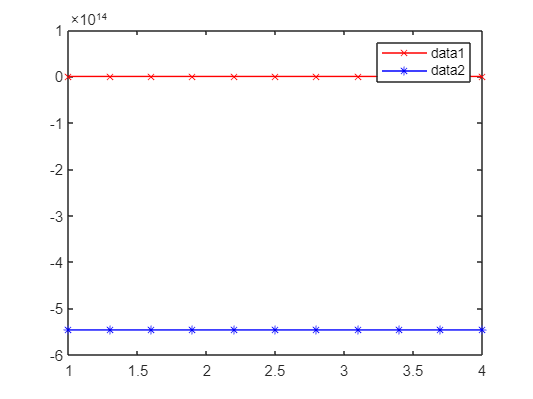


% re-install the values of solution at x=1 and x=4 for plotting
Y(1)=1; 


% exact solution provided in problem sheet
Yexact=-2*log(X)-1/3 +(8/3)*log(4)+(4/3)*(1-2*log(4))./X;

% plot exact and FE solution
plot(X,Yexact,'-xr', X,Y,'-*b');
hold on 

% compute error
err=sum((Yexact-Y).^2)/sum(Yexact.^2);


%
legend('show', 'Location','northeast')
%
hold off